clearvars
sincalData = readtable("res.xlsx");

pythonData = readtable("busData.csv");

sincalVMag = sincalData.V_Vn___;
sincalVAng = sincalData.x_V___;

% get rid of degree symbol at the end
stringVoltage = strrep(pythonData.voltages_polar_pu_, "°", "");
splitted = split(stringVoltage, "∠");
pythonVMag = double(splitted(:, 1)); pythonVAng = double(splitted(:, 2));

format long
tolerance = 3e-3;
sincalVMag = sincalVMag(2:end); % get rid of zeroth bus on sincal
sincalVAng = sincalVAng(2:end);
sincalVMag = sincalVMag/100; % converter percent to per unit

% relative normalisation
diffVMag = (pythonVMag - sincalVMag); 
diffVAng = (pythonVAng - sincalVAng);

isSatisfiedMag = all(boolean(abs(diffVMag) < tolerance) == true) % pu is in range 1

isSatisfiedMag = logical
   1


isSatisfiedAng = all(boolean(abs(diffVAng)./360 < tolerance) == true)  % degrees is in range 360

isSatisfiedAng = logical
   1


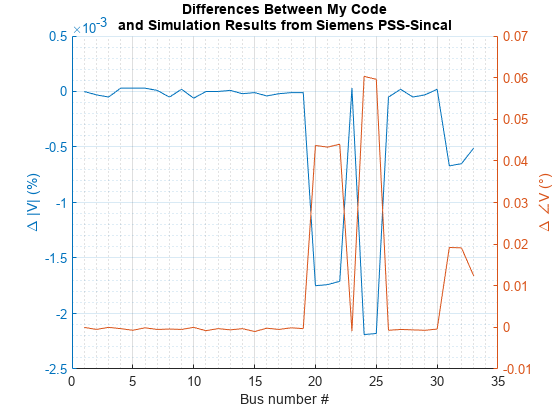


figure()
hold on
grid on
grid minor
yyaxis left
plot(diffVMag)
ylabel("\Delta |V| (%)")
yyaxis right
plot(diffVAng)
ylabel("\Delta ∠V (°)")
xlabel("Bus number #")
title(["Differences Between My Code", "and Simulation Results from Siemens PSS-Sincal"])

saveas(gcf, "comparison.emf")
saveas(gcf, "comparison.png")